
% Project Title: Particle-Swarm-Optimization-using-Matlab
% This program not only calls the PSO function but it is used to analyse
% the effect of population size.
%Use with caution
% chi = k

Average_BestCost = zeros(1,9);
Best_Cost = zeros(1,100);
Best_CostSoFar = 10^7;
for k = 1:9
    for j = 1:100 
        
        %% Problem Definiton
        
        problem.CostFunction = @(x) project_problem(x);  % Cost Function
        problem.nVar = 4;       % Number of Unknown (Decision) Variables
        problem.VarMin = [0 0 0 0];  % Lower Bound of Decision Variables
        problem.VarMax =  [10 10 10 10];   % Upper Bound of Decision Variables
        
        %% Parameters of PSO
        phi1=2.05;
        phi2=2.05;
        kappa=1;
        phi=phi1+phi2;
        % phi = phi1
        chi=2*kappa/abs(2-phi-sqrt(phi^2-4*phi));
        params.MaxIt = 100;        % Maximum Number of Iterations
        params.nPop = k*50;           % Population Size (Swarm Size)
        params.w = chi;               % Intertia Coefficient
        params.wdamp = 0.3925;        % Damping Ratio of Inertia Coefficient
        params.c1 = chi*phi1;              % Personal Acceleration Coefficient
        params.c2 = chi*phi2;              % Social Acceleration Coefficient
        params.ShowIterInfo = true; % Flag for Showing Iteration Informatin
        
        %% Calling PSO
        
        out = PSO(problem, params);
        
        BestSol = out.BestSol;
        BestCosts = out.BestCosts;
        
        %% Results
        
        
        %Evaluate constraints and store
        constraint_store = zeros(1,7);
        constraint_store_index = zeros(1,7);
        Result = BestSol.Position;
        x(1) = Result(:,1);
        x(2) = Result(:,2);
        x(3) = Result(:,3);
        x(4) = Result(:,4);
        P = 6000;
        W = 14;
        E = 30*10^6;
        G = 12*10^6;
        Tau_max = 13600;
        rho_max = 30000;
        rai_max = 0.25;
        Tau_a = P/(2^0.5*x(1)*x(2));
        M = P*(W+(x(2)/2));
        F = ((x(1)+x(3))/2)^2;
        R = (x(2)^2/4 + F)^0.5;
        J = 2*((2^0.5*x(1)*x(2)) * (x(2)^2/12 + F));
        Tau_b = (M*R)/J;
        Tau = (Tau_a^2 + ((2*Tau_a*Tau_b) * (x(2)/(2*R))) + Tau_b^2)^0.5;
        rho = (6*P*W)/(x(4)*x(3)^2);
        rai = (4*P*W^3)/(x(4)*x(3)^3*E);
        r = ((4.013*E) * ((x(3)^2 * x(4)^6)/36)^0.5)/W^2;
        a = (1) - ((x(3)/(2*W)) * (E/(4*G))^0.5);
        Pc = r*a;
        
        cO = [];
        %objective function(minimization)
        of = 1.1047*x(1)^2*x(2) + 0.04811*x(3)* (x(4)*(14+x(2)));
        
        %All constraints converted to <= type
        cO(1)=Tau - Tau_max;
        cO(2)=rho - rho_max;
        cO(3)= x(1) - x(4);
        cO(4)= 0.1047*x(1)^2 + 0.04811*x(3)* (x(4)*(14+x(2))) - 5;
        cO(5)= 0.125 - x(1);
        cO(6)= rai - rai_max;
        cO(7)= P -Pc;
        % Checking if constraints are satisfied
        for i = 1:length(cO)
        %           constraint_store(i) = cO(i);
            constraint_store_index(i) = cO(i) < 0;    
        end
        %Storing Best_Cost
        Best_Cost(j) = BestSol.Cost;

        %Storing Necessary data
        if Best_Cost(j) < Best_CostSoFar && sum(constraint_store_index) == 7
            Best_CostSoFar = Best_Cost(j);
            save 'LeastCost_Info','BestSol','cO','params'
        end
    end
    %Calculate Average best cost/Npop used
    Average_BestCost(k) = median(Best_Cost);
end

Iteration 1: Best Cost = 10013.2514
Iteration 2: Best Cost = 6.4778
Iteration 3: Best Cost = 3.8183
Iteration 4: Best Cost = 3.6921
Iteration 5: Best Cost = 3.6921
Iteration 6: Best Cost = 3.6921
Iteration 7: Best Cost = 3.6742
Iteration 8: Best Cost = 3.6713
Iteration 9: Best Cost = 3.65
Iteration 10: Best Cost = 3.3833
Iteration 11: Best Cost = 3.3833
Iteration 12: Best Cost = 3.3664
Iteration 13: Best Cost = 3.3441
Iteration 14: Best Cost = 3.341
Iteration 15: Best Cost = 3.3401
Iteration 16: Best Cost = 3.3396
Iteration 17: Best Cost = 3.2611
Iteration 18: Best Cost = 3.2459
Iteration 19: Best Cost = 3.2311
Iteration 20: Best Cost = 3.2308
Iteration 21: Best Cost = 3.2256
Iteration 22: Best Cost = 3.2256
Iteration 23: Best Cost = 3.225
Iteration 24: Best Cost = 3.225
Iteration 25: Best Cost = 3.225
Iteration 26: Best Cost = 3.225
Iteration 27: Best Cost = 3.2248
Iteration 28: Best Cost = 3.2248
Iteration 29: Best Cost = 3.2248
Iteration 30: Best Cost = 3.2247
Iteration 31: Best Cos

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 10009.936
Iteration 2: Best Cost = 7.7557
Iteration 3: Best Cost = 4.2819
Iteration 4: Best Cost = 4.1095
Iteration 5: Best Cost = 3.5647
Iteration 6: Best Cost = 3.4989
Iteration 7: Best Cost = 3.435
Iteration 8: Best Cost = 3.3823
Iteration 9: Best Cost = 3.3787
Iteration 10: Best Cost = 3.3785
Iteration 11: Best Cost = 3.3746
Iteration 12: Best Cost = 3.3462
Iteration 13: Best Cost = 3.3299
Iteration 14: Best Cost = 3.3184
Iteration 15: Best Cost = 3.3155
Iteration 16: Best Cost = 3.3155
Iteration 17: Best Cost = 3.3152
Iteration 18: Best Cost = 3.3125
Iteration 19: Best Cost = 3.3119
Iteration 20: Best Cost = 3.3054
Iteration 21: Best Cost = 3.303
Iteration 22: Best Cost = 3.3016
Iteration 23: Best Cost = 3.3008
Iteration 24: Best Cost = 3.2979
Iteration 25: Best Cost = 3.297
Iteration 26: Best Cost = 3.297
Iteration 27: Best Cost = 3.2949
Iteration 28: Best Cost = 3.2947
Iteration 29: Best Cost = 3.2947
Iteration 30: Best Cost = 3.2943
Iteration 31: Best C

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 10015.7842
Iteration 2: Best Cost = 10010.4399
Iteration 3: Best Cost = 10009.5122
Iteration 4: Best Cost = 10007.2711
Iteration 5: Best Cost = 10005.7964
Iteration 6: Best Cost = 10004.959
Iteration 7: Best Cost = 10003.8557
Iteration 8: Best Cost = 10003.8541
Iteration 9: Best Cost = 10003.8059
Iteration 10: Best Cost = 10003.796
Iteration 11: Best Cost = 5.9702
Iteration 12: Best Cost = 5.2565
Iteration 13: Best Cost = 4.9575
Iteration 14: Best Cost = 4.9575
Iteration 15: Best Cost = 4.4389
Iteration 16: Best Cost = 4.4249
Iteration 17: Best Cost = 4.3727
Iteration 18: Best Cost = 4.332
Iteration 19: Best Cost = 4.2575
Iteration 20: Best Cost = 4.2385
Iteration 21: Best Cost = 4.2385
Iteration 22: Best Cost = 4.2382
Iteration 23: Best Cost = 4.233
Iteration 24: Best Cost = 4.2298
Iteration 25: Best Cost = 4.228
Iteration 26: Best Cost = 4.2275
Iteration 27: Best Cost = 4.2275
Iteration 28: Best Cost = 4.2275
Iteration 29: Best Cost = 4.2275
Iteration 30: Bes

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 10013.1389
Iteration 2: Best Cost = 10007.3795
Iteration 3: Best Cost = 5.026
Iteration 4: Best Cost = 3.9036
Iteration 5: Best Cost = 3.3007
Iteration 6: Best Cost = 3.135
Iteration 7: Best Cost = 2.9841
Iteration 8: Best Cost = 2.9584
Iteration 9: Best Cost = 2.942
Iteration 10: Best Cost = 2.9175
Iteration 11: Best Cost = 2.896
Iteration 12: Best Cost = 2.8914
Iteration 13: Best Cost = 2.8886
Iteration 14: Best Cost = 2.8877
Iteration 15: Best Cost = 2.8817
Iteration 16: Best Cost = 2.8797
Iteration 17: Best Cost = 2.879
Iteration 18: Best Cost = 2.8783
Iteration 19: Best Cost = 2.8758
Iteration 20: Best Cost = 2.8741
Iteration 21: Best Cost = 2.8733
Iteration 22: Best Cost = 2.873
Iteration 23: Best Cost = 2.873
Iteration 24: Best Cost = 2.8729
Iteration 25: Best Cost = 2.8729
Iteration 26: Best Cost = 2.8728
Iteration 27: Best Cost = 2.8728
Iteration 28: Best Cost = 2.8211
Iteration 29: Best Cost = 2.8048
Iteration 30: Best Cost = 2.7942
Iteration 31: Best

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 10010.5517
Iteration 2: Best Cost = 10008.7472
Iteration 3: Best Cost = 10007.1112
Iteration 4: Best Cost = 6.0997
Iteration 5: Best Cost = 5.1804
Iteration 6: Best Cost = 4.6542
Iteration 7: Best Cost = 4.2126
Iteration 8: Best Cost = 4.2125
Iteration 9: Best Cost = 4.1456
Iteration 10: Best Cost = 4.1007
Iteration 11: Best Cost = 4.1007
Iteration 12: Best Cost = 4.098
Iteration 13: Best Cost = 4.04
Iteration 14: Best Cost = 4.038
Iteration 15: Best Cost = 4.038
Iteration 16: Best Cost = 4.0365
Iteration 17: Best Cost = 4.0356
Iteration 18: Best Cost = 4.0353
Iteration 19: Best Cost = 4.0353
Iteration 20: Best Cost = 4.0346
Iteration 21: Best Cost = 4.0339
Iteration 22: Best Cost = 4.0338
Iteration 23: Best Cost = 4.0337
Iteration 24: Best Cost = 4.0337
Iteration 25: Best Cost = 4.0337
Iteration 26: Best Cost = 4.0337
Iteration 27: Best Cost = 4.0337
Iteration 28: Best Cost = 4.0337
Iteration 29: Best Cost = 4.0337
Iteration 30: Best Cost = 4.0337
Iteration 31

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 10007.6628
Iteration 2: Best Cost = 6.7484
Iteration 3: Best Cost = 6.7484
Iteration 4: Best Cost = 5.3539
Iteration 5: Best Cost = 4.4034
Iteration 6: Best Cost = 4.222
Iteration 7: Best Cost = 4.0976
Iteration 8: Best Cost = 4.0319
Iteration 9: Best Cost = 4.0035
Iteration 10: Best Cost = 3.9992
Iteration 11: Best Cost = 3.9992
Iteration 12: Best Cost = 3.9868
Iteration 13: Best Cost = 3.9668
Iteration 14: Best Cost = 3.9645
Iteration 15: Best Cost = 3.9597
Iteration 16: Best Cost = 3.9546
Iteration 17: Best Cost = 3.9546
Iteration 18: Best Cost = 3.9492
Iteration 19: Best Cost = 3.9428
Iteration 20: Best Cost = 3.9418
Iteration 21: Best Cost = 3.9405
Iteration 22: Best Cost = 3.9394
Iteration 23: Best Cost = 3.9393
Iteration 24: Best Cost = 3.9371
Iteration 25: Best Cost = 3.9359
Iteration 26: Best Cost = 3.9359
Iteration 27: Best Cost = 3.9356
Iteration 28: Best Cost = 3.9352
Iteration 29: Best Cost = 3.9352
Iteration 30: Best Cost = 3.9352
Iteration 31: Be

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 10015.2765
Iteration 2: Best Cost = 10009.7448
Iteration 3: Best Cost = 10008.5794
Iteration 4: Best Cost = 10007.6779
Iteration 5: Best Cost = 10005.7851
Iteration 6: Best Cost = 10005.536
Iteration 7: Best Cost = 10005.167
Iteration 8: Best Cost = 7.1765
Iteration 9: Best Cost = 7.1761
Iteration 10: Best Cost = 7.1761
Iteration 11: Best Cost = 7.1642
Iteration 12: Best Cost = 6.8236
Iteration 13: Best Cost = 6.7069
Iteration 14: Best Cost = 6.5125
Iteration 15: Best Cost = 6.2997
Iteration 16: Best Cost = 6.0045
Iteration 17: Best Cost = 6.0045
Iteration 18: Best Cost = 6.0012
Iteration 19: Best Cost = 5.9974
Iteration 20: Best Cost = 5.996
Iteration 21: Best Cost = 5.9842
Iteration 22: Best Cost = 5.962
Iteration 23: Best Cost = 5.9357
Iteration 24: Best Cost = 5.9281
Iteration 25: Best Cost = 5.9276
Iteration 26: Best Cost = 5.9276
Iteration 27: Best Cost = 5.9274
Iteration 28: Best Cost = 5.9274
Iteration 29: Best Cost = 5.9273
Iteration 30: Best Cost = 5.

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 5.7525
Iteration 2: Best Cost = 3.9076
Iteration 3: Best Cost = 3.6694
Iteration 4: Best Cost = 3.2476
Iteration 5: Best Cost = 3.1203
Iteration 6: Best Cost = 2.8935
Iteration 7: Best Cost = 2.866
Iteration 8: Best Cost = 2.848
Iteration 9: Best Cost = 2.844
Iteration 10: Best Cost = 2.8362
Iteration 11: Best Cost = 2.8347
Iteration 12: Best Cost = 2.8294
Iteration 13: Best Cost = 2.8289
Iteration 14: Best Cost = 2.8285
Iteration 15: Best Cost = 2.8284
Iteration 16: Best Cost = 2.8284
Iteration 17: Best Cost = 2.8282
Iteration 18: Best Cost = 2.82
Iteration 19: Best Cost = 2.8071
Iteration 20: Best Cost = 2.8012
Iteration 21: Best Cost = 2.7982
Iteration 22: Best Cost = 2.7936
Iteration 23: Best Cost = 2.7688
Iteration 24: Best Cost = 2.7688
Iteration 25: Best Cost = 2.7414
Iteration 26: Best Cost = 2.7134
Iteration 27: Best Cost = 2.6782
Iteration 28: Best Cost = 2.675
Iteration 29: Best Cost = 2.6628
Iteration 30: Best Cost = 2.6541
Iteration 31: Best Cost =

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 10003.0917
Iteration 2: Best Cost = 5.1476
Iteration 3: Best Cost = 4.1655
Iteration 4: Best Cost = 3.7745
Iteration 5: Best Cost = 3.7046
Iteration 6: Best Cost = 3.6775
Iteration 7: Best Cost = 3.5335
Iteration 8: Best Cost = 3.5286
Iteration 9: Best Cost = 3.5255
Iteration 10: Best Cost = 3.5237
Iteration 11: Best Cost = 3.5207
Iteration 12: Best Cost = 3.5195
Iteration 13: Best Cost = 3.5193
Iteration 14: Best Cost = 3.519
Iteration 15: Best Cost = 3.5178
Iteration 16: Best Cost = 3.5178
Iteration 17: Best Cost = 3.5178
Iteration 18: Best Cost = 3.5176
Iteration 19: Best Cost = 3.5123
Iteration 20: Best Cost = 3.5094
Iteration 21: Best Cost = 3.5043
Iteration 22: Best Cost = 3.4978
Iteration 23: Best Cost = 3.496
Iteration 24: Best Cost = 3.496
Iteration 25: Best Cost = 3.4751
Iteration 26: Best Cost = 3.4751
Iteration 27: Best Cost = 3.4724
Iteration 28: Best Cost = 3.4698
Iteration 29: Best Cost = 3.4666
Iteration 30: Best Cost = 3.464
Iteration 31: Best 

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 10004.7214
Iteration 2: Best Cost = 12.3566
Iteration 3: Best Cost = 4.2763
Iteration 4: Best Cost = 4.2763
Iteration 5: Best Cost = 4.1312
Iteration 6: Best Cost = 3.829
Iteration 7: Best Cost = 3.8099
Iteration 8: Best Cost = 3.7265
Iteration 9: Best Cost = 3.6867
Iteration 10: Best Cost = 3.6743
Iteration 11: Best Cost = 3.6616
Iteration 12: Best Cost = 3.6599
Iteration 13: Best Cost = 3.6249
Iteration 14: Best Cost = 3.622
Iteration 15: Best Cost = 3.621
Iteration 16: Best Cost = 3.604
Iteration 17: Best Cost = 3.5224
Iteration 18: Best Cost = 3.4575
Iteration 19: Best Cost = 3.3574
Iteration 20: Best Cost = 3.3348
Iteration 21: Best Cost = 3.3348
Iteration 22: Best Cost = 3.3323
Iteration 23: Best Cost = 3.3323
Iteration 24: Best Cost = 3.3286
Iteration 25: Best Cost = 3.3278
Iteration 26: Best Cost = 3.3222
Iteration 27: Best Cost = 3.2109
Iteration 28: Best Cost = 2.896
Iteration 29: Best Cost = 2.7357
Iteration 30: Best Cost = 2.5313
Iteration 31: Best 

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 8.5315
Iteration 2: Best Cost = 8.5315
Iteration 3: Best Cost = 4.2945
Iteration 4: Best Cost = 3.9809
Iteration 5: Best Cost = 3.4962
Iteration 6: Best Cost = 3.4018
Iteration 7: Best Cost = 3.0988
Iteration 8: Best Cost = 2.9526
Iteration 9: Best Cost = 2.92
Iteration 10: Best Cost = 2.8546
Iteration 11: Best Cost = 2.8094
Iteration 12: Best Cost = 2.8094
Iteration 13: Best Cost = 2.7398
Iteration 14: Best Cost = 2.7289
Iteration 15: Best Cost = 2.7148
Iteration 16: Best Cost = 2.7025
Iteration 17: Best Cost = 2.7016
Iteration 18: Best Cost = 2.7011
Iteration 19: Best Cost = 2.6999
Iteration 20: Best Cost = 2.6974
Iteration 21: Best Cost = 2.6949
Iteration 22: Best Cost = 2.694
Iteration 23: Best Cost = 2.694
Iteration 24: Best Cost = 2.683
Iteration 25: Best Cost = 2.6807
Iteration 26: Best Cost = 2.6778
Iteration 27: Best Cost = 2.6766
Iteration 28: Best Cost = 2.6713
Iteration 29: Best Cost = 2.6659
Iteration 30: Best Cost = 2.665
Iteration 31: Best Cost =

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 5.4924
Iteration 2: Best Cost = 3.8107
Iteration 3: Best Cost = 3.4367
Iteration 4: Best Cost = 3.2387
Iteration 5: Best Cost = 3.1901
Iteration 6: Best Cost = 3.0394
Iteration 7: Best Cost = 2.9604
Iteration 8: Best Cost = 2.809
Iteration 9: Best Cost = 2.7492
Iteration 10: Best Cost = 2.6715
Iteration 11: Best Cost = 2.6658
Iteration 12: Best Cost = 2.6517
Iteration 13: Best Cost = 2.6399
Iteration 14: Best Cost = 2.6296
Iteration 15: Best Cost = 2.605
Iteration 16: Best Cost = 2.598
Iteration 17: Best Cost = 2.5944
Iteration 18: Best Cost = 2.5762
Iteration 19: Best Cost = 2.5756
Iteration 20: Best Cost = 2.5723
Iteration 21: Best Cost = 2.5716
Iteration 22: Best Cost = 2.5716
Iteration 23: Best Cost = 2.5689
Iteration 24: Best Cost = 2.5687
Iteration 25: Best Cost = 2.5681
Iteration 26: Best Cost = 2.568
Iteration 27: Best Cost = 2.567
Iteration 28: Best Cost = 2.5658
Iteration 29: Best Cost = 2.5655
Iteration 30: Best Cost = 2.5652
Iteration 31: Best Cost 

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 5.8057
Iteration 2: Best Cost = 3.2298
Iteration 3: Best Cost = 3.2298
Iteration 4: Best Cost = 3.2248
Iteration 5: Best Cost = 3.1408
Iteration 6: Best Cost = 3.1342
Iteration 7: Best Cost = 3.0026
Iteration 8: Best Cost = 3.0002
Iteration 9: Best Cost = 2.9886
Iteration 10: Best Cost = 2.9579
Iteration 11: Best Cost = 2.9579
Iteration 12: Best Cost = 2.9579
Iteration 13: Best Cost = 2.8613
Iteration 14: Best Cost = 2.2172
Iteration 15: Best Cost = 2.2109
Iteration 16: Best Cost = 2.1468
Iteration 17: Best Cost = 2.1433
Iteration 18: Best Cost = 2.1332
Iteration 19: Best Cost = 2.1169
Iteration 20: Best Cost = 2.1102
Iteration 21: Best Cost = 2.1038
Iteration 22: Best Cost = 2.0972
Iteration 23: Best Cost = 2.0971
Iteration 24: Best Cost = 2.0965
Iteration 25: Best Cost = 2.0957
Iteration 26: Best Cost = 2.0946
Iteration 27: Best Cost = 2.0705
Iteration 28: Best Cost = 2.0705
Iteration 29: Best Cost = 2.0677
Iteration 30: Best Cost = 2.0632
Iteration 31: Best 

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 3.8921
Iteration 2: Best Cost = 2.9955
Iteration 3: Best Cost = 2.4015
Iteration 4: Best Cost = 2.3589
Iteration 5: Best Cost = 2.3555
Iteration 6: Best Cost = 2.3396
Iteration 7: Best Cost = 2.3024
Iteration 8: Best Cost = 2.2538
Iteration 9: Best Cost = 2.234
Iteration 10: Best Cost = 2.1961
Iteration 11: Best Cost = 2.1703
Iteration 12: Best Cost = 2.1495
Iteration 13: Best Cost = 2.1457
Iteration 14: Best Cost = 2.1457
Iteration 15: Best Cost = 2.1418
Iteration 16: Best Cost = 2.14
Iteration 17: Best Cost = 2.1345
Iteration 18: Best Cost = 2.1326
Iteration 19: Best Cost = 2.1227
Iteration 20: Best Cost = 2.1146
Iteration 21: Best Cost = 2.0974
Iteration 22: Best Cost = 2.0355
Iteration 23: Best Cost = 1.9963
Iteration 24: Best Cost = 1.9678
Iteration 25: Best Cost = 1.9623
Iteration 26: Best Cost = 1.9623
Iteration 27: Best Cost = 1.9573
Iteration 28: Best Cost = 1.9554
Iteration 29: Best Cost = 1.955
Iteration 30: Best Cost = 1.9534
Iteration 31: Best Cost

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 5.162
Iteration 2: Best Cost = 3.2034
Iteration 3: Best Cost = 2.6964
Iteration 4: Best Cost = 2.3515
Iteration 5: Best Cost = 2.2201
Iteration 6: Best Cost = 2.1882
Iteration 7: Best Cost = 2.1717
Iteration 8: Best Cost = 2.1522
Iteration 9: Best Cost = 2.1429
Iteration 10: Best Cost = 2.1429
Iteration 11: Best Cost = 2.1428
Iteration 12: Best Cost = 2.1417
Iteration 13: Best Cost = 2.1414
Iteration 14: Best Cost = 2.1408
Iteration 15: Best Cost = 2.1408
Iteration 16: Best Cost = 2.1354
Iteration 17: Best Cost = 2.1159
Iteration 18: Best Cost = 2.1098
Iteration 19: Best Cost = 2.1003
Iteration 20: Best Cost = 2.0936
Iteration 21: Best Cost = 2.0891
Iteration 22: Best Cost = 2.0794
Iteration 23: Best Cost = 2.062
Iteration 24: Best Cost = 2.0272
Iteration 25: Best Cost = 2.0272
Iteration 26: Best Cost = 2.018
Iteration 27: Best Cost = 1.9985
Iteration 28: Best Cost = 1.9985
Iteration 29: Best Cost = 1.9962
Iteration 30: Best Cost = 1.9954
Iteration 31: Best Cos

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 2.8414
Iteration 2: Best Cost = 2.8414
Iteration 3: Best Cost = 2.5498
Iteration 4: Best Cost = 2.4003
Iteration 5: Best Cost = 2.3832
Iteration 6: Best Cost = 2.3093
Iteration 7: Best Cost = 2.2847
Iteration 8: Best Cost = 2.2838
Iteration 9: Best Cost = 2.2782
Iteration 10: Best Cost = 2.2549
Iteration 11: Best Cost = 2.2481
Iteration 12: Best Cost = 2.2428
Iteration 13: Best Cost = 2.2428
Iteration 14: Best Cost = 2.2427
Iteration 15: Best Cost = 2.2416
Iteration 16: Best Cost = 2.2402
Iteration 17: Best Cost = 2.2132
Iteration 18: Best Cost = 2.2052
Iteration 19: Best Cost = 2.1954
Iteration 20: Best Cost = 2.193
Iteration 21: Best Cost = 2.1881
Iteration 22: Best Cost = 2.1686
Iteration 23: Best Cost = 2.1244
Iteration 24: Best Cost = 2.1225
Iteration 25: Best Cost = 2.1136
Iteration 26: Best Cost = 2.0988
Iteration 27: Best Cost = 2.0975
Iteration 28: Best Cost = 2.088
Iteration 29: Best Cost = 2.0863
Iteration 30: Best Cost = 2.0811
Iteration 31: Best Co

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 5.1725
Iteration 2: Best Cost = 3.4117
Iteration 3: Best Cost = 2.7585
Iteration 4: Best Cost = 2.7585
Iteration 5: Best Cost = 2.7585
Iteration 6: Best Cost = 2.6858
Iteration 7: Best Cost = 2.6361
Iteration 8: Best Cost = 2.631
Iteration 9: Best Cost = 2.5612
Iteration 10: Best Cost = 2.2036
Iteration 11: Best Cost = 2.021
Iteration 12: Best Cost = 1.9783
Iteration 13: Best Cost = 1.9737
Iteration 14: Best Cost = 1.9499
Iteration 15: Best Cost = 1.918
Iteration 16: Best Cost = 1.918
Iteration 17: Best Cost = 1.9168
Iteration 18: Best Cost = 1.9159
Iteration 19: Best Cost = 1.9132
Iteration 20: Best Cost = 1.9125
Iteration 21: Best Cost = 1.7788
Iteration 22: Best Cost = 1.7788
Iteration 23: Best Cost = 1.7714
Iteration 24: Best Cost = 1.759
Iteration 25: Best Cost = 1.7522
Iteration 26: Best Cost = 1.7472
Iteration 27: Best Cost = 1.7464
Iteration 28: Best Cost = 1.7456
Iteration 29: Best Cost = 1.7455
Iteration 30: Best Cost = 1.745
Iteration 31: Best Cost =

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 6.9435
Iteration 2: Best Cost = 3.955
Iteration 3: Best Cost = 3.5268
Iteration 4: Best Cost = 3.1603
Iteration 5: Best Cost = 3.1463
Iteration 6: Best Cost = 3.1398
Iteration 7: Best Cost = 3.1376
Iteration 8: Best Cost = 3.136
Iteration 9: Best Cost = 3.1095
Iteration 10: Best Cost = 3.1032
Iteration 11: Best Cost = 3.1032
Iteration 12: Best Cost = 3.0956
Iteration 13: Best Cost = 3.0846
Iteration 14: Best Cost = 3.0757
Iteration 15: Best Cost = 3.0673
Iteration 16: Best Cost = 3.0471
Iteration 17: Best Cost = 3.0425
Iteration 18: Best Cost = 3.042
Iteration 19: Best Cost = 3.0409
Iteration 20: Best Cost = 3.0403
Iteration 21: Best Cost = 3.0338
Iteration 22: Best Cost = 3.0254
Iteration 23: Best Cost = 3.0249
Iteration 24: Best Cost = 3.0228
Iteration 25: Best Cost = 2.9945
Iteration 26: Best Cost = 2.9851
Iteration 27: Best Cost = 2.9747
Iteration 28: Best Cost = 2.9669
Iteration 29: Best Cost = 2.7681
Iteration 30: Best Cost = 2.2846
Iteration 31: Best Cos

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 3.4309
Iteration 2: Best Cost = 3.4309
Iteration 3: Best Cost = 3.1202
Iteration 4: Best Cost = 3.1202
Iteration 5: Best Cost = 3.0278
Iteration 6: Best Cost = 3.0144
Iteration 7: Best Cost = 2.9317
Iteration 8: Best Cost = 2.4444
Iteration 9: Best Cost = 2.144
Iteration 10: Best Cost = 2.1338
Iteration 11: Best Cost = 2.1306
Iteration 12: Best Cost = 2.1248
Iteration 13: Best Cost = 2.1093
Iteration 14: Best Cost = 2.1068
Iteration 15: Best Cost = 2.101
Iteration 16: Best Cost = 2.0905
Iteration 17: Best Cost = 2.0886
Iteration 18: Best Cost = 2.0886
Iteration 19: Best Cost = 2.0854
Iteration 20: Best Cost = 2.0823
Iteration 21: Best Cost = 2.0795
Iteration 22: Best Cost = 2.0795
Iteration 23: Best Cost = 2.0795
Iteration 24: Best Cost = 2.079
Iteration 25: Best Cost = 2.0782
Iteration 26: Best Cost = 2.0781
Iteration 27: Best Cost = 2.0781
Iteration 28: Best Cost = 2.078
Iteration 29: Best Cost = 2.0779
Iteration 30: Best Cost = 2.0778
Iteration 31: Best Cost

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 3.8904
Iteration 2: Best Cost = 2.6604
Iteration 3: Best Cost = 2.6604
Iteration 4: Best Cost = 2.3508
Iteration 5: Best Cost = 2.3273
Iteration 6: Best Cost = 2.3175
Iteration 7: Best Cost = 2.2455
Iteration 8: Best Cost = 2.2455
Iteration 9: Best Cost = 2.2428
Iteration 10: Best Cost = 2.2224
Iteration 11: Best Cost = 2.2207
Iteration 12: Best Cost = 2.2169
Iteration 13: Best Cost = 2.2169
Iteration 14: Best Cost = 2.2146
Iteration 15: Best Cost = 2.2133
Iteration 16: Best Cost = 2.2128
Iteration 17: Best Cost = 2.2128
Iteration 18: Best Cost = 2.2128
Iteration 19: Best Cost = 2.2126
Iteration 20: Best Cost = 2.2126
Iteration 21: Best Cost = 2.2125
Iteration 22: Best Cost = 2.2125
Iteration 23: Best Cost = 2.2125
Iteration 24: Best Cost = 2.2124
Iteration 25: Best Cost = 2.2122
Iteration 26: Best Cost = 2.2121
Iteration 27: Best Cost = 2.2121
Iteration 28: Best Cost = 2.2121
Iteration 29: Best Cost = 2.2121
Iteration 30: Best Cost = 2.2121
Iteration 31: Best 

ans = 'BestSol'

ans = 'cO'

ans = 'params'

Iteration 1: Best Cost = 4.9669
Iteration 2: Best Cost = 4.1649
Iteration 3: Best Cost = 3.6049
Iteration 4: Best Cost = 3.558
Iteration 5: Best Cost = 3.5097
Iteration 6: Best Cost = 3.474
Iteration 7: Best Cost = 2.8895
Iteration 8: Best Cost = 2.6634
Iteration 9: Best Cost = 2.4813
Iteration 10: Best Cost = 2.3687
Iteration 11: Best Cost = 2.2618
Iteration 12: Best Cost = 2.2507
Iteration 13: Best Cost = 2.2368
Iteration 14: Best Cost = 1.9183
Iteration 15: Best Cost = 1.806
Iteration 16: Best Cost = 1.7747
Iteration 17: Best Cost = 1.7738
Iteration 18: Best Cost = 1.7619
Iteration 19: Best Cost = 1.7546
Iteration 20: Best Cost = 1.7495
Iteration 21: Best Cost = 1.7495
Iteration 22: Best Cost = 1.7486
Iteration 23: Best Cost = 1.7463
Iteration 24: Best Cost = 1.746
Iteration 25: Best Cost = 1.7458
Iteration 26: Best Cost = 1.7458
Iteration 27: Best Cost = 1.7458
Iteration 28: Best Cost = 1.7457
Iteration 29: Best Cost = 1.7456
Iteration 30: Best Cost = 1.7456
Iteration 31: Best Cost

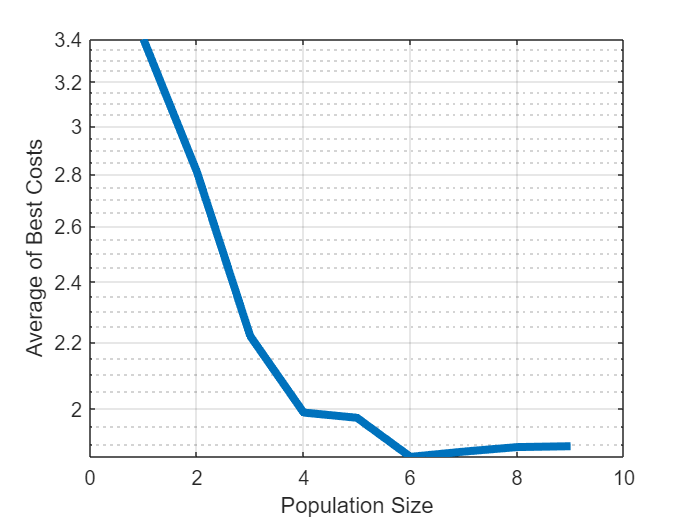


figure;
% plot(Average_BestCosts, 'LineWidth', 4);
semilogy(Average_BestCost, 'LineWidth', 4);
xlabel('Population Size');
ylabel('Average of Best Costs');
grid on;